Is there a relationship between the flash response of a cell and its excitatory and inhibitory inputs to the same stimulus? Here, it appears that while maximum firing rate (in first 150ms) is dependent on poth peak inward current and total excitatory charge, it shows no association with peak outward current or total inhibitory charge. This supports the notion that the difference between UP and DOWN ON DS cells is a difference in excitatory inputs (cells have a difference in peak firing rate, a difference in excitation, no difference in inhibition, + peak firing rate is dependent only on excitation).

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

peakFlash_Ex_Ups = [];
peakFlash_Inh_Ups = [];
peakFlash_Ex_Downs = [];
peakFlash_Inh_Downs = [];

windowTime = 40; %ms
stepSize = 5; %ms
upPSTH_Ex = [];
upPSTH_Inh = [];
downPSTH_Ex = [];
downPSTH_Inh = [];

flashResponseTotalTime = 3; %s
SR = 1000; %hz

chargeFlash_Ex_Ups = [];
chargeFlash_Inh_Ups = [];
chargeFlash_Ex_Downs = [];
chargeFlash_Inh_Downs = [];

%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'Intracellular'}; %child field name should be one of these. Priority is in given order
priorityOrder_2c = {'_ff'; 'Extracellular'};
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation'};
mustHave_2b = {'Inhibition'};
mustHave_2c = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
cantHave_2c = {'Intracellular', 'Potassium'};
rigMandates = []; %

%ups first
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc_excitation, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_extracellular, pass_ex] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2c, mustHave_2c, cantHave_2c, rigMandates);
    
    if ~pass_ex
        extracellularTotalTime = loc_extracellular.meta.preTime + loc_extracellular.meta.stimTime + loc_extracellular.meta.tailTime;
        if extracellularTotalTime ~= 3000
            continue
        end
    end
    
    if pass_ex
        continue
    end
    
    %get spike data
    spikeTimes_i = loc_extracellular.Analysis_Results.allSpikeTimes;
    
    numBins = round(3000/stepSize);
    results_i = zeros(numel(spikeTimes_i), numBins);
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        firingRates = spikeTimesToFiringRates(s, 0, 3000, windowTime, stepSize);
        results_i(j, :) = firingRates * 1000;
    end
    
    
    if j == 1
        spikeResults = results_i;
    else
        spikeResults = mean(results_i);
    end
    
    %get excitation data if it exists
    if ~pass && loc_excitation.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    
    if ~pass
        %get whole cell data
        disp(struct_i.cellID)
        peakFlash_Ex_Ups = [peakFlash_Ex_Ups; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch)];
        chargeFlash_Ex_Ups = [chargeFlash_Ex_Ups; mean(loc_excitation.Analysis_Results.totalChargeByEpoch)];
        upPSTH_Ex = [upPSTH_Ex; spikeResults];
    end
    
    [loc_inhibition, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass && loc_inhibition.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        peakFlash_Inh_Ups = [peakFlash_Inh_Ups; mean(loc_inhibition.Analysis_Results.ON_maxPositivePeakByEpoch)];
        chargeFlash_Inh_Ups = [chargeFlash_Inh_Ups; mean(loc_inhibition.Analysis_Results.totalChargeByEpoch)];
        upPSTH_Inh = [upPSTH_Inh; spikeResults];
    end
    
end

SHOKR71Lc5
SHOKR71Lc6
SHOKR71Lc11
SHOKR73Lc5
SHOKR73Lc7
SHOKR73Lc8
SHOKR73Lc9
SHOKR75Lc2
SHOKR75Lc4
SHOKR75Lc6
SHOKR75Lc10
SHOKR75Lc13
SHOKR76Lc1
SHOKR76Lc12
SHOKR77Lc2
SHOKR77Lc6
SHOKR77Lc9
SHOKR83Lc8
SHOKR85Lc4
SHOKR85Lc1
SHOKR85Lc7
SHOKR85Lc11



for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc_excitation, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_extracellular, pass_ex] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2c, mustHave_2c, cantHave_2c, rigMandates);
    
    if ~pass_ex
        extracellularTotalTime = loc_extracellular.meta.preTime + loc_extracellular.meta.stimTime + loc_extracellular.meta.tailTime;
        if extracellularTotalTime ~= 3000
            continue
        end
    end
    
    if pass_ex
        continue
    end
    
    %get spike data
    spikeTimes_i = loc_extracellular.Analysis_Results.allSpikeTimes;
    
    numBins = round(3000/stepSize);
    results_i = zeros(numel(spikeTimes_i), numBins);
    for j = 1:numel(spikeTimes_i)
        s = spikeTimes_i{j};
        firingRates = spikeTimesToFiringRates(s, 0, 3000, windowTime, stepSize);
        results_i(j, :) = firingRates * 1000;
    end
    
    
    if j == 1
        spikeResults = results_i;
    else
        spikeResults = mean(results_i);
    end
    
    %get excitation data if it exists
    if ~pass && loc_excitation.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    
    if ~pass
        %get whole cell data
        disp(struct_i.cellID)
        peakFlash_Ex_Downs = [peakFlash_Ex_Downs; mean(loc_excitation.Analysis_Results.ON_maxNegativePeakByEpoch)];
        chargeFlash_Ex_Downs = [chargeFlash_Ex_Downs; mean(loc_excitation.Analysis_Results.totalChargeByEpoch)];
        downPSTH_Ex = [downPSTH_Ex; spikeResults];
    end
    
    [loc_inhibition, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if ~pass && loc_inhibition.Analysis_Results.totalTime ~= 3000
        pass = 1;
    end
    if ~pass
        peakFlash_Inh_Downs = [peakFlash_Inh_Downs; mean(loc_inhibition.Analysis_Results.ON_maxPositivePeakByEpoch)];
        chargeFlash_Inh_Downs = [chargeFlash_Inh_Downs; mean(loc_inhibition.Analysis_Results.totalChargeByEpoch)];
        downPSTH_Inh = [downPSTH_Inh; spikeResults];
    end
end

SHOKR71Lc9
SHOKR71Lc10
SHOKR73Lc2
SHOKR73Lc4
SHOKR75Lc5
SHOKR75Lc12
SHOKR76Lc3
SHOKR77Lc1
SHOKR77Lc4
SHOKR77Lc5
SHOKR77Lc7
SHOKR77Lc8
SHOKR83Lc4
SHOKR83Lc7
SHOKR85Lc2
SHOKR85Lc6
SHOKR85Lc10
SHOKR101Lc6


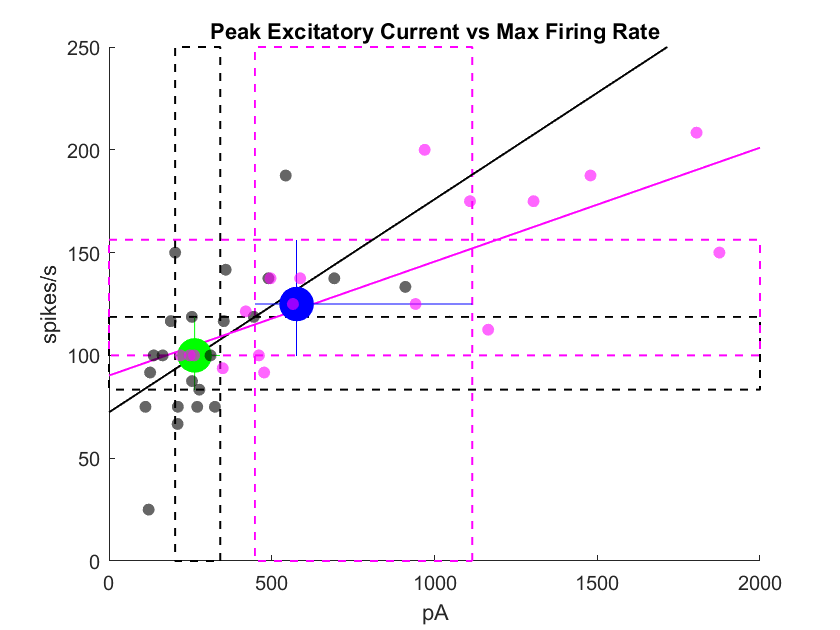

%calculate max firing rate overall and in the first 150ms
xvals = [stepSize/2:stepSize:3000-stepSize/2];

upFRs_Ex = upPSTH_Ex(:, xvals>1000);
upFRs_Inh = upPSTH_Inh(:, xvals>1000);
downFRs_Ex = downPSTH_Ex(:, xvals>1000);
downFRs_Inh = downPSTH_Inh(:, xvals>1000);

upMaxFR_Ex = max(upFRs_Ex, [], 2);
upMaxFR_Inh = max(upFRs_Inh, [], 2);
downMaxFR_Ex = max(downFRs_Ex, [], 2);
downMaxFR_Inh = max(downFRs_Inh, [], 2);

% upFirst150ms_Ex = upPSTH_Ex(:, xvals>1000 & xvals < 1150);
% upFirst150ms_Inh = upPSTH_Inh(:, xvals>1000 & xvals< 1150);
% downFirst150ms_Ex = downPSTH_Ex(:, xvals>1000 & xvals < 1150);
% downFirst150ms_Inh = downPSTH_Inh(:, xvals>1000 & xvals< 1150);
% 
% upMaxFirst150_Ex = max(upFirst150ms_Ex, [], 2);
% upMaxFirst150_Inh = max(upFirst150ms_Inh, [], 2);
% downMaxFirst150_Ex = max(downFirst150ms_Ex, [], 2);
% downMaxFirst150_Inh = max(downFirst150ms_Inh, [], 2);

upXVals = -peakFlash_Ex_Ups;
upYVals = upMaxFR_Ex;
downXVals = -peakFlash_Ex_Downs;
downYVals = downMaxFR_Ex;

mdlUp = fitlm(upXVals, upYVals);
mdlDown = fitlm(downXVals, downYVals);

xlimMin = 0; xlimMax = 2000;
ylimMin = 0; ylimMax = 250;
fitQueriesUp = [xlimMin:10:xlimMax];
fitQueriesDown = [xlimMin:10:xlimMax];
upMdlPredictions = feval(mdlUp, fitQueriesUp);
downMdlPredictions = feval(mdlDown, fitQueriesDown);

medianXUp = median([upXVals]);
medianYUp = median([upYVals]);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap([upXVals], 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap([upYVals], 10000);

medianXDown = median([downXVals]);
medianYDown = median([downYVals]);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap([downXVals], 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap([downYVals], 10000);

f = figure();
title('Peak Excitatory Current vs Max Firing Rate')
hold on
plot([xlimMin xlimMax xlimMax xlimMin xlimMin], [yUpER2, yUpER2 -yUpER1 -yUpER1 yUpER2]+medianYUp, '--k', 'LineWidth', 1)
plot([xUpER2, xUpER2 -xUpER1 -xUpER1 xUpER2]+medianXUp, [ylimMin ylimMax ylimMax ylimMin ylimMin], '--k', 'LineWidth', 1)
plot([xlimMin xlimMax xlimMax xlimMin xlimMin], [yDownER2, yDownER2 -yDownER1 -yDownER1 yDownER2]+medianYDown, '--m', 'LineWidth', 1)
plot([xDownER2, xDownER2 -xDownER1 -xDownER1 xDownER2]+medianXDown, [ylimMin ylimMax ylimMax ylimMin ylimMin], '--m', 'LineWidth', 1)
plot(fitQueriesUp, upMdlPredictions, 'k', 'LineWidth', 1)
plot(fitQueriesDown, downMdlPredictions, 'm', 'LineWidth', 1)
scatter(medianXUp, medianYUp, 300, 'filled', 'g')
plot([-xUpER1, xUpER2]+medianXUp, [medianYUp, medianYUp], 'g')
plot([medianXUp, medianXUp], [-yUpER1, yUpER2]+medianYUp, 'g')
scatter(medianXDown, medianYDown, 300, 'filled', 'b')
plot([-xDownER1, xDownER2]+medianXDown, [medianYDown, medianYDown], 'b')
plot([medianXDown, medianXDown], [-yDownER1, yDownER2]+medianYDown, 'b')
scatter(upXVals, upYVals, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downXVals, downYVals, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlim([xlimMin, xlimMax])
ylim([ylimMin, ylimMax])
xlabel('pA')
ylabel('spikes/s')

[corrCoef, up_pval] = corr(upXVals, upYVals, 'type', 'Spearman')

corrCoef = 0.5742

up_pval = 0.0052

[corrCoef, down_pval] = corr(downXVals, downYVals, 'type', 'Spearman')

corrCoef = 0.8011

down_pval = 6.4689e-05

[corrCoef, total_pval] = corr([upXVals; downXVals], [upYVals; downYVals], 'type', 'Spearman')

corrCoef = 0.7292

total_pval = 9.4733e-08

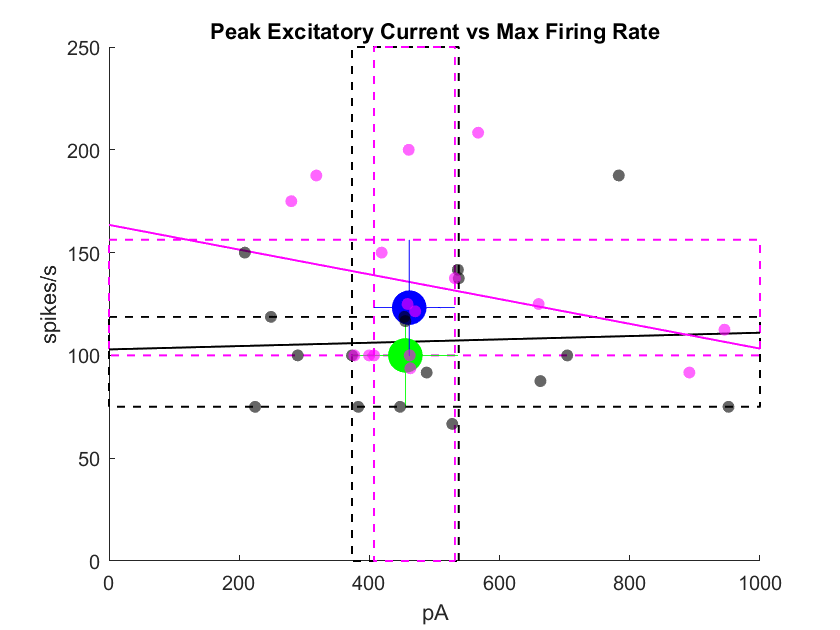


upXVals = peakFlash_Inh_Ups;
upYVals = upMaxFR_Inh;
downXVals = peakFlash_Inh_Downs;
downYVals = downMaxFR_Inh;

mdlUp = fitlm(upXVals, upYVals);
mdlDown = fitlm(downXVals, downYVals);

xlimMin = 0; xlimMax = 1000;
ylimMin = 0; ylimMax = 250;
fitQueriesUp = [xlimMin:10:xlimMax];
fitQueriesDown = [xlimMin:10:xlimMax];
upMdlPredictions = feval(mdlUp, fitQueriesUp);
downMdlPredictions = feval(mdlDown, fitQueriesDown);

medianXUp = median([upXVals]);
medianYUp = median([upYVals]);
[~, ~, xUpER1, xUpER2] = medianCI95Bootstrap([upXVals], 10000);
[~, ~, yUpER1, yUpER2] = medianCI95Bootstrap([upYVals], 10000);

medianXDown = median([downXVals]);
medianYDown = median([downYVals]);
[~, ~, xDownER1, xDownER2] = medianCI95Bootstrap([downXVals], 10000);
[~, ~, yDownER1, yDownER2] = medianCI95Bootstrap([downYVals], 10000);

f = figure();
title('Peak Excitatory Current vs Max Firing Rate')
hold on
plot([xlimMin xlimMax xlimMax xlimMin xlimMin], [yUpER2, yUpER2 -yUpER1 -yUpER1 yUpER2]+medianYUp, '--k', 'LineWidth', 1)
plot([xUpER2, xUpER2 -xUpER1 -xUpER1 xUpER2]+medianXUp, [ylimMin ylimMax ylimMax ylimMin ylimMin], '--k', 'LineWidth', 1)
plot([xlimMin xlimMax xlimMax xlimMin xlimMin], [yDownER2, yDownER2 -yDownER1 -yDownER1 yDownER2]+medianYDown, '--m', 'LineWidth', 1)
plot([xDownER2, xDownER2 -xDownER1 -xDownER1 xDownER2]+medianXDown, [ylimMin ylimMax ylimMax ylimMin ylimMin], '--m', 'LineWidth', 1)
plot(fitQueriesUp, upMdlPredictions, 'k', 'LineWidth', 1)
plot(fitQueriesDown, downMdlPredictions, 'm', 'LineWidth', 1)
scatter(medianXUp, medianYUp, 300, 'filled', 'g')
plot([-xUpER1, xUpER2]+medianXUp, [medianYUp, medianYUp], 'g')
plot([medianXUp, medianXUp], [-yUpER1, yUpER2]+medianYUp, 'g')
scatter(medianXDown, medianYDown, 300, 'filled', 'b')
plot([-xDownER1, xDownER2]+medianXDown, [medianYDown, medianYDown], 'b')
plot([medianXDown, medianXDown], [-yDownER1, yDownER2]+medianYDown, 'b')
scatter(upXVals, upYVals, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downXVals, downYVals, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlim([xlimMin, xlimMax])
ylim([ylimMin, ylimMax])
xlabel('pA')
ylabel('spikes/s')

[corrCoef, up_pval] = corr(upXVals, upYVals, 'type', 'Spearman')

corrCoef = 0.0062

up_pval = 0.9812

[corrCoef, down_pval] = corr(downXVals, downYVals, 'type', 'Spearman')

corrCoef = -0.1601

down_pval = 0.5536

[corrCoef, total_pval] = corr([upXVals; downXVals], [upYVals; downYVals], 'type', 'Spearman')

corrCoef = -0.0457

total_pval = 0.8005

## Excitability: AUC of the PSTH vs Total Charge (excitation & inhibition)

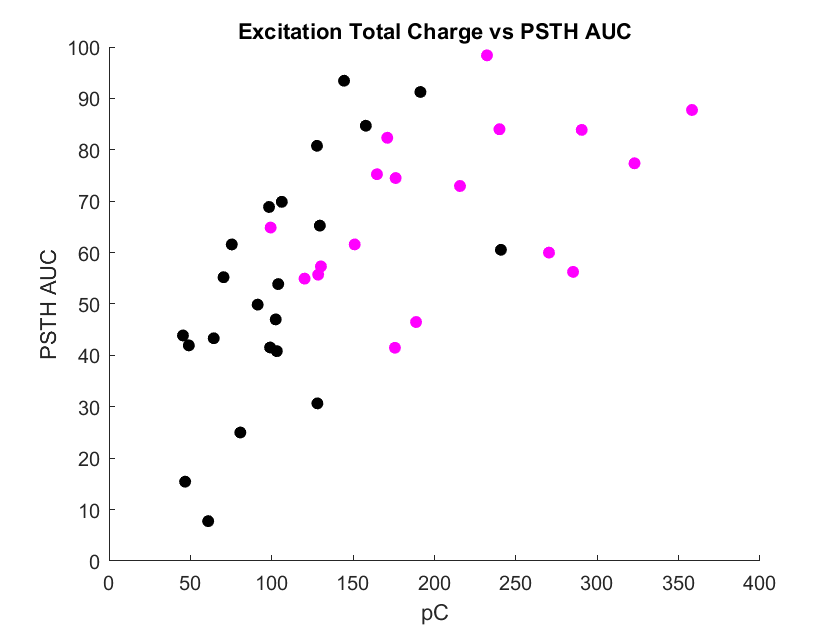


upTotalSpikes_Ex = trapz(upPSTH_Ex, 2)/200;
downTotalSpikes_Ex = trapz(downPSTH_Ex, 2)/200;

figure
title('Excitation Total Charge vs PSTH AUC'),
hold on
scatter(-chargeFlash_Ex_Ups, upTotalSpikes_Ex, 'k', 'filled')
scatter(-chargeFlash_Ex_Downs, downTotalSpikes_Ex, 'm', 'filled')
xlabel('pC')
ylabel('PSTH AUC')

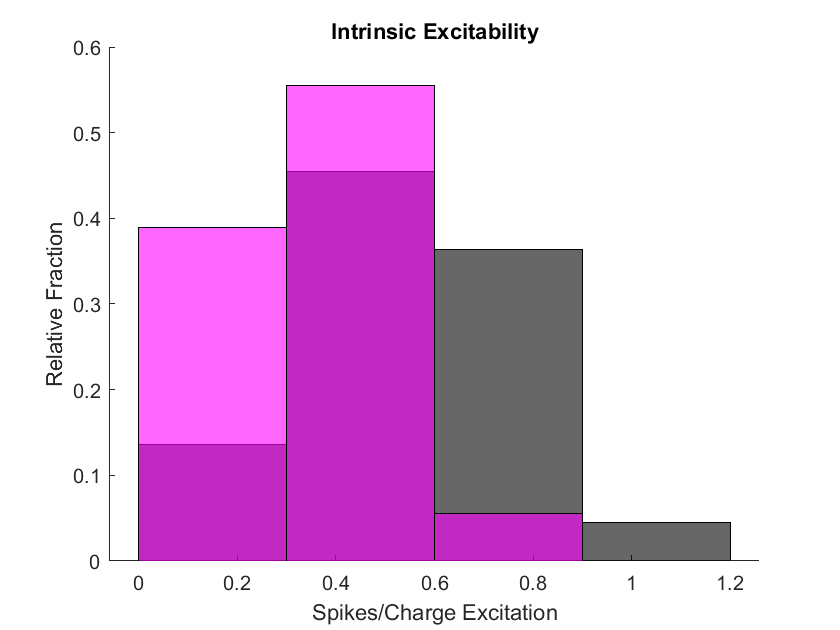

upExcitability = upTotalSpikes_Ex./-chargeFlash_Ex_Ups;
downExcitability = downTotalSpikes_Ex./-chargeFlash_Ex_Downs;

figure
title('Intrinsic Excitability')
hold on
h1 = histogram(upExcitability, 'FaceColor', 'k', 'Normalization','probability');
h2 = histogram(downExcitability, 'FaceColor', 'm', 'Normalization','probability');
h2.BinWidth = h1.BinWidth;
xlabel('Spikes/Charge Excitation')
ylabel('Relative Fraction')

p = ranksum(upExcitability, downExcitability)

p = 0.0049

medianUp = median(upExcitability)

medianUp = 0.5275

medianDown = median(downExcitability)

medianDown = 0.3791

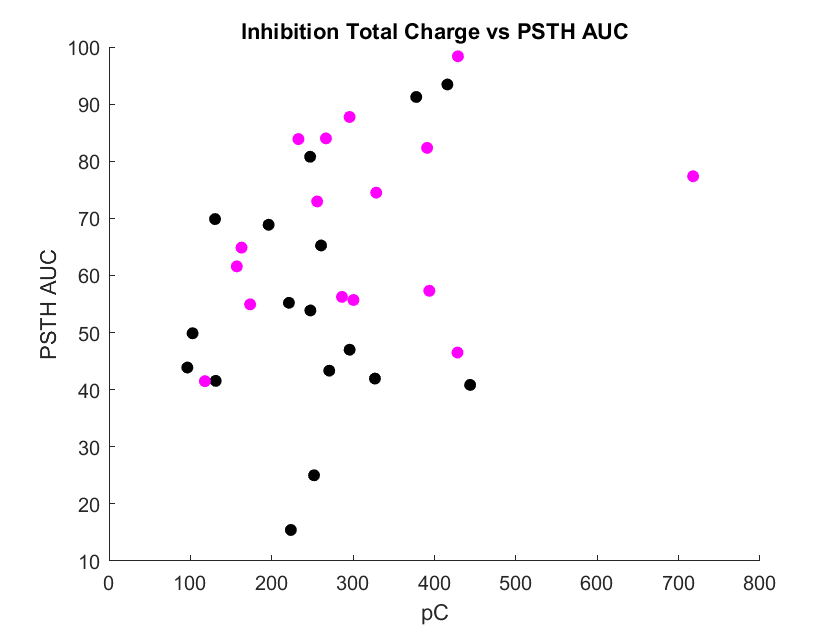


upTotalSpikes_Inh = trapz(upPSTH_Inh, 2)/200;
downTotalSpikes_Inh = trapz(downPSTH_Inh, 2)/200;

figure
title('Inhibition Total Charge vs PSTH AUC'),
hold on
scatter(chargeFlash_Inh_Ups, upTotalSpikes_Inh, 'k', 'filled')
scatter(chargeFlash_Inh_Downs, downTotalSpikes_Inh, 'm', 'filled')
xlabel('pC')
ylabel('PSTH AUC')

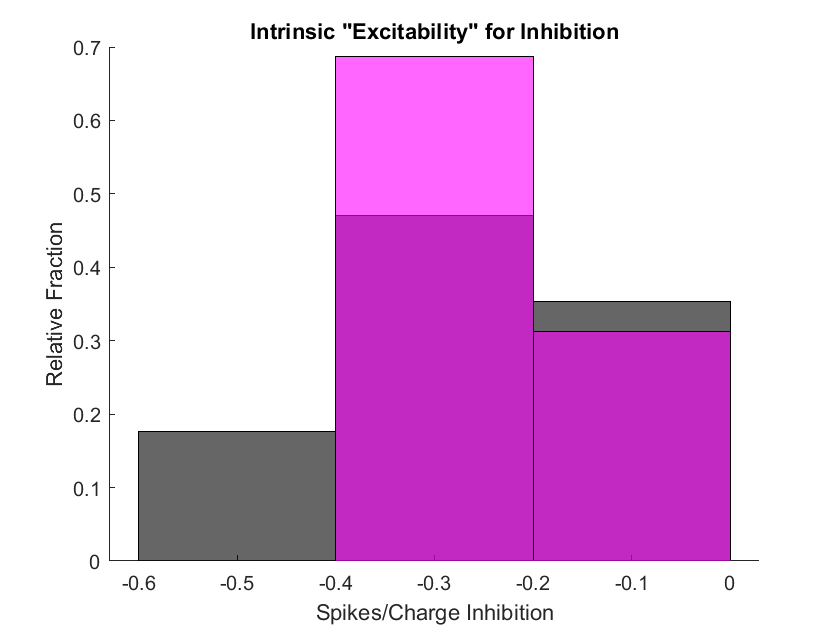

upInh_Excitability = upTotalSpikes_Inh./-chargeFlash_Inh_Ups;
downInh_Excitability = downTotalSpikes_Inh./-chargeFlash_Inh_Downs;

figure
title('Intrinsic "Excitability" for Inhibition')
hold on
h1 = histogram(upInh_Excitability, 'FaceColor', 'k', 'Normalization','probability');
h2 = histogram(downInh_Excitability, 'FaceColor', 'm', 'Normalization','probability');
h2.BinWidth = h1.BinWidth;
xlabel('Spikes/Charge Inhibition')
ylabel('Relative Fraction')


p = ranksum(upInh_Excitability, downInh_Excitability)

p = 0.7595

medianUp = median(upInh_Excitability)

medianUp = -0.2417

medianDown = median(downInh_Excitability)

medianDown = -0.2573